# P06: Sistemas de inferencia difusos (FIS)

## Integrantes

- Alberto Camarena Rodríguez

- Jonathan Lozada García

- José Aaron Barbosa Mercado

- Luis Francisco Castro Hernández 

- Teddy Xavier Muñoz Ceballos 

## Objetivos

- Implementar sistemas de inferencia difusos, utilizando MATLAB

- Decodificar sistemas de inferencia difusos implementados en Simulink

## Introduccion

El modelo difuso propuesto por Tsukamoto en 1979 se caracteriza por presentar el consecuente de cada regla difusa mediante un conjunto difuso con una función de pertenencia monótona. La salida inferida por cada regla es un valor numérico inducido por el grado de pertenencia. La salida total se toma como la media ponderada de todas las salidas parciales. Este modelo permite eliminar el consumo de tiempo de desfusificación, sin embargo, no es muy utilizado por no ser tan transparente como Mamdani o Sugeno. El mecanismo de inferencia no sigue estrictamente la regla composicional de inferencia y la salida siempre es numérica, incluso cuando las salidas son difusas. 

Resumiendo; en este modelo la función consecuente es un set difuso con una función monotónica e.g. Si X es A y Y es B entonces Z es C. La salida de cada regla se define como un valor exacto inducido por la pertenencia a cada regla. Cada regla tiene una salida exacta. No se requiere desfusificación ya que agrega la salidas exactas de cada regla usando el promedio ponderado.

## Problema 1

Se llama a la herramienta grafica del Fuzzy Logic Toolbox;

fuzzyLogicDesigner();

Primero se cambia el nombre de la entrada en el recuadro Name, a servicio. Se hara lo mismo con la segunda entrada, por comida.

Desde el menu Edit se pueden agregar variables.

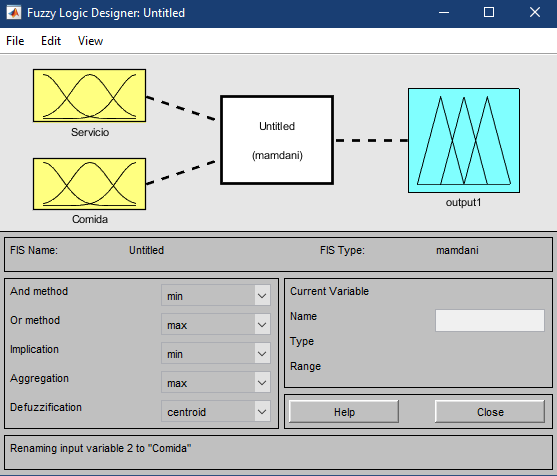

Dando doble click en una variable se puede cambiar su universo de discurso, en este caso [0 100].

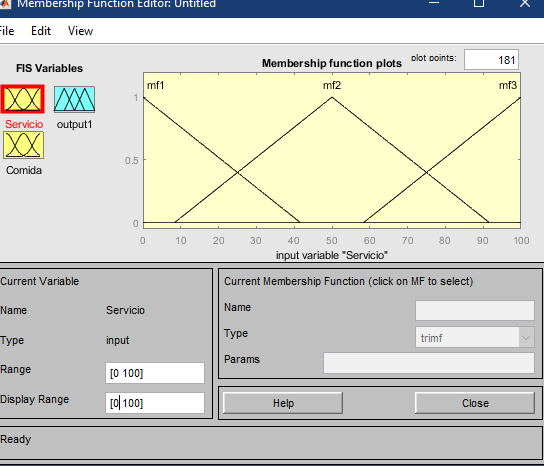

Se cambiara tambien el nombre de la salida por propina, y se ajustara su universo de discurso de [0 15].

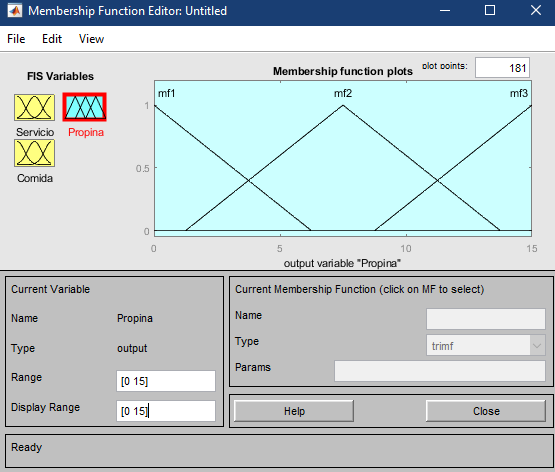

A continuacion se asignaron funciones de membresia en base a nuestras experiencias como consumidores.

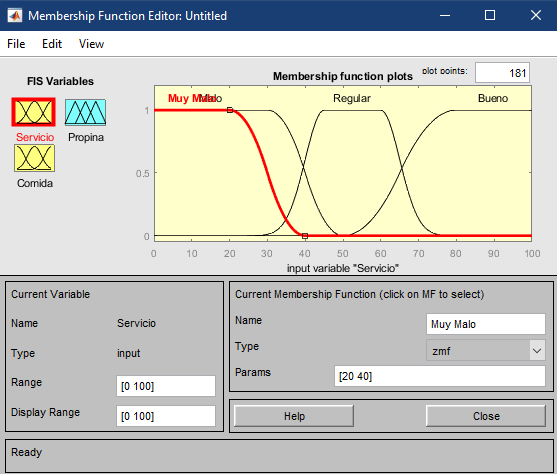

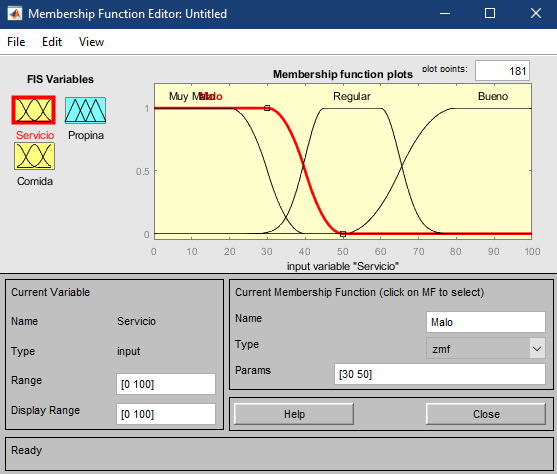

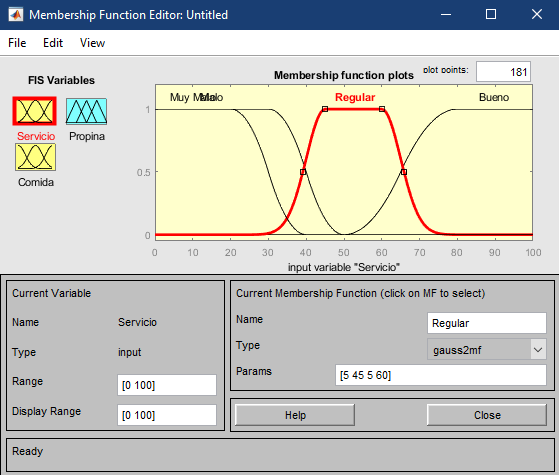

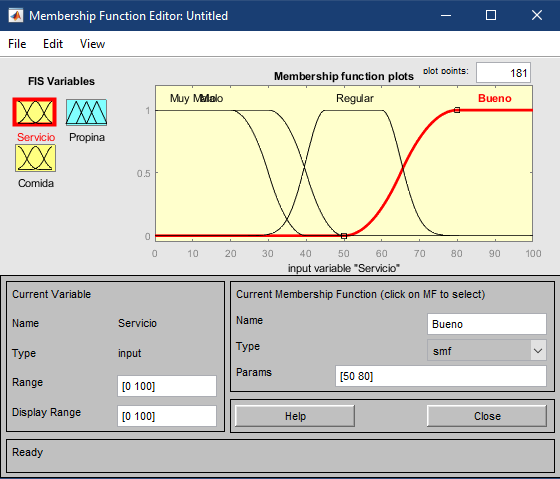

Se hizo lo mismo para la variable comida.

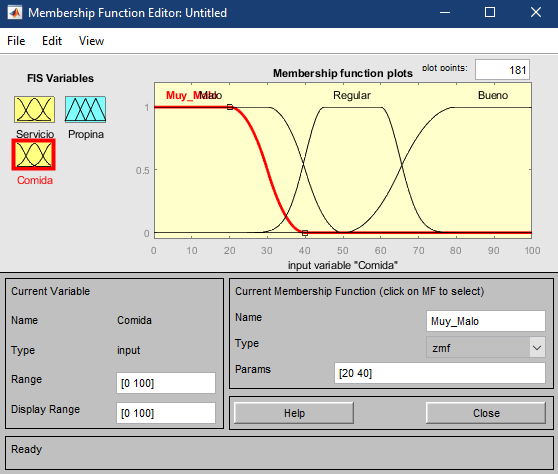

Para la salida Propina se utilizaron funciones de transferencia trapezoidales.

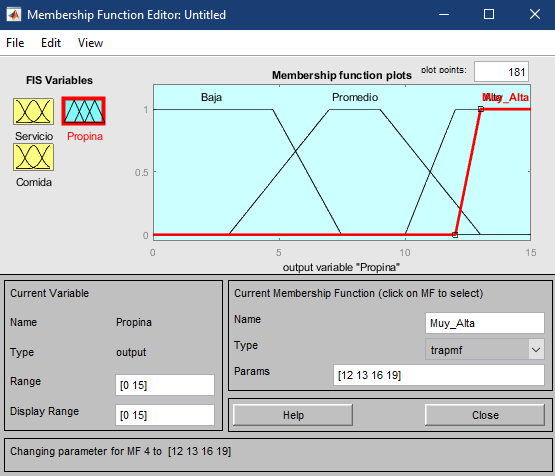

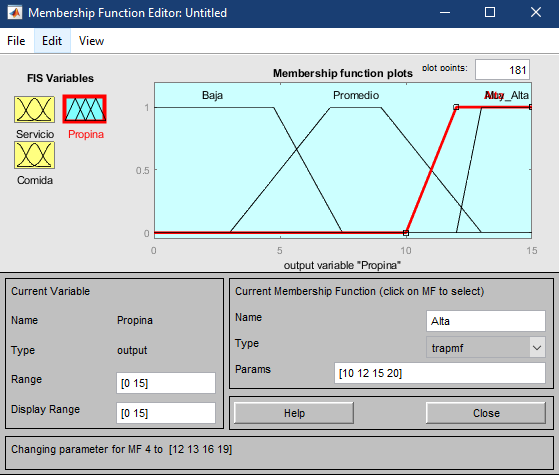

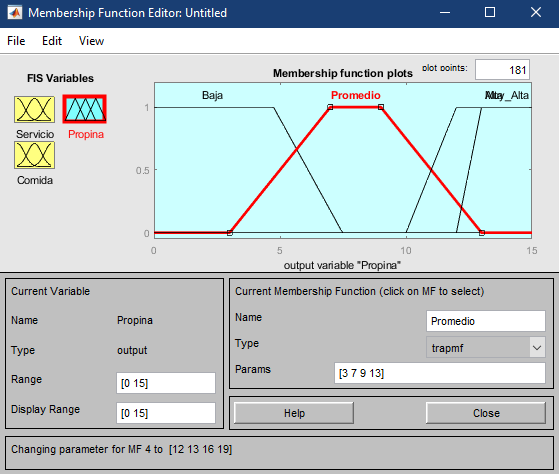

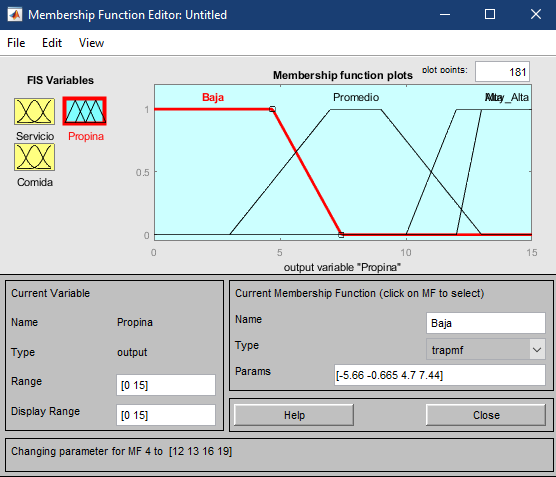

Las reglas si-entonces se hacen dando doble click en el modelo de controlador difuso mamdani.

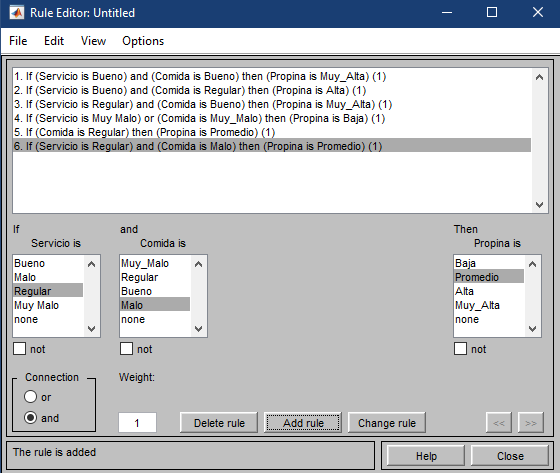

Podemos observar los resultados de propina para diferentes valores de servicio y comida.

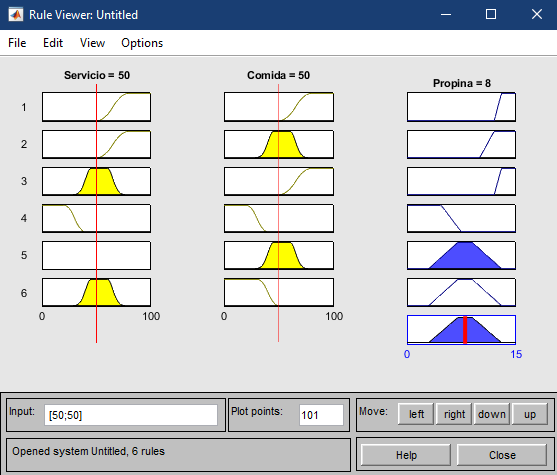

Aunque esta comparacion se ve mejor en la grafica de superficie.

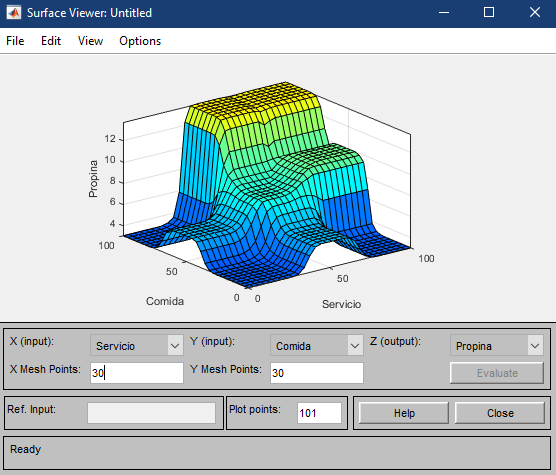

Se puede observar como este modelo tiene un mejor desempeño cuando se observa que da mas importancia a calificaciones altas en la comida que en el servicio, cosa que nosotros (en experiencia propia) hacemos.

El problema del modelo se da en los saltos bruscos. Por ejemplo, si la comida tiene una calificacion cercana a 100, se dara mucha mas propina si el servicio es de 40, en comparacion a si es de 30. Cuando en la relaidad, el cambio deberia ser mas suave.

## Problema 2

Se hará la implementación de un FIS en Simulink para el control del nivel de agua de un tanque. Para lo cual se llama el comando:

open_system('sltank');

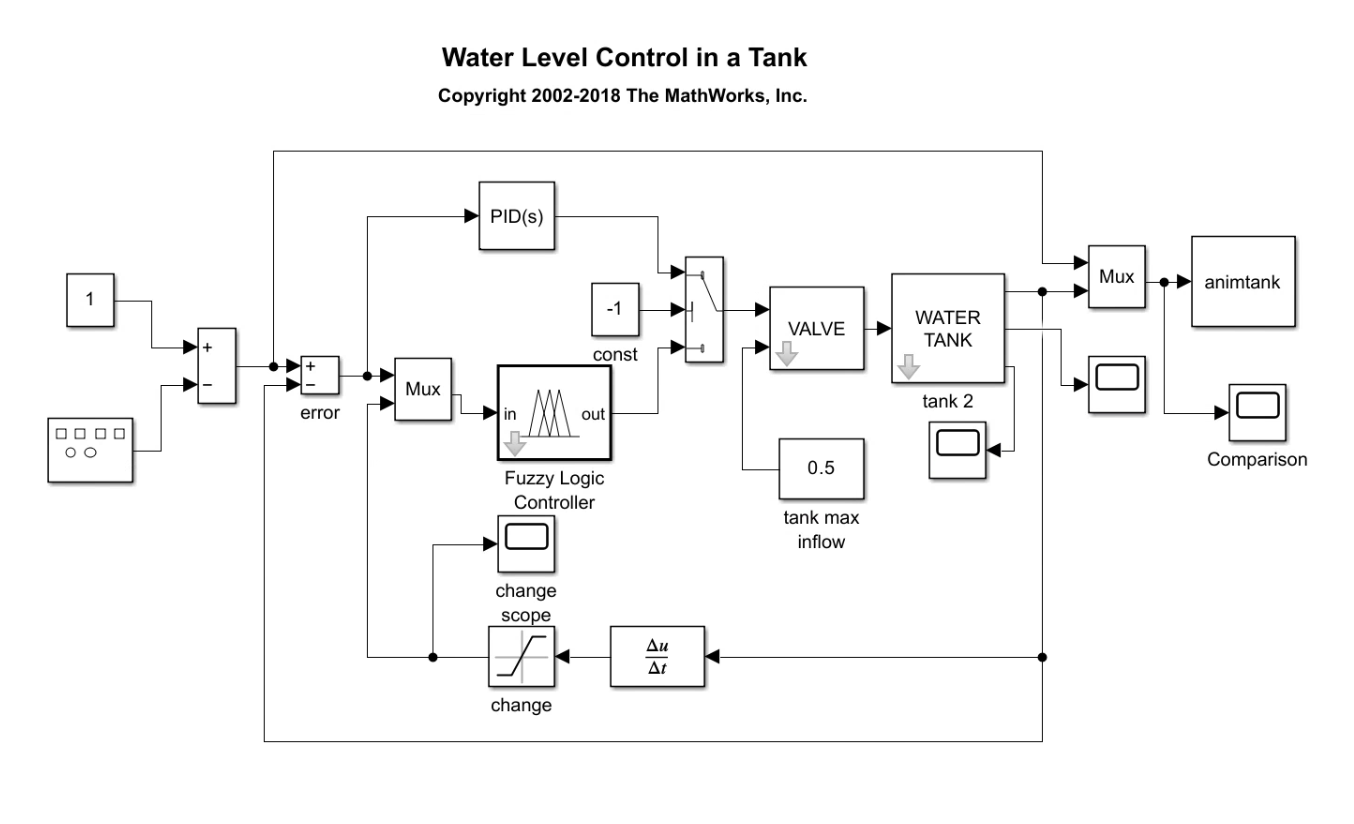

Que nos genera dentro del workspace una variable llamada tank de tipo mamfis, que indica que nuestro sistema de inferencia es mandami.

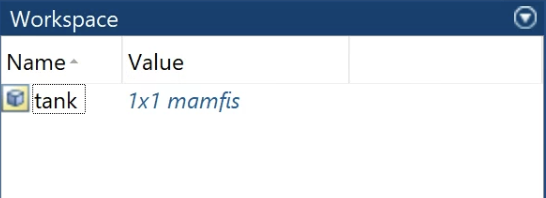

Ahora exploramos el mismo sistema pero con ayuda del app de Fussy Designer, para poder responder a las preguntas, esto lo logramos corriendo el comando:

fuzzyLogicDesigner(tank);

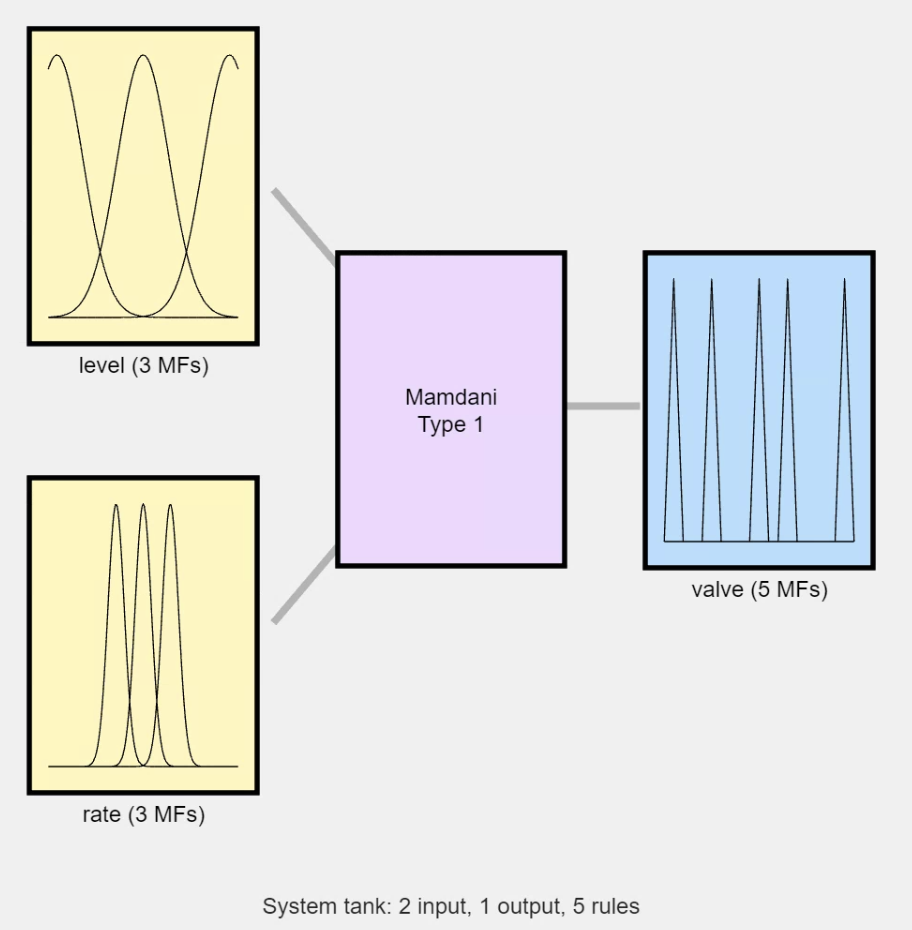

2.1 ¿Cuántas variables lingúistcas se tienen?

R.- Dos (2) de entrada; level y rate. Y una (1) de salida llamada valve.

2.2 ¿Cuál es el universo de discurso de cada una?

R.- level	[-1.1 1.1] - rate [-0.35 0.35] - valve	[-1 1]

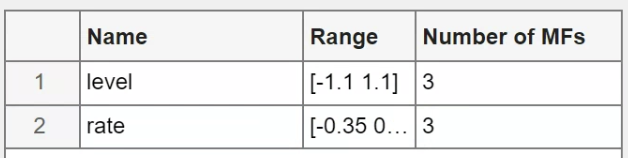

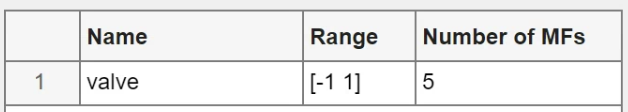

2.3 Grafica las conjuntos difusos de cada variable lingüistica

R.-

level

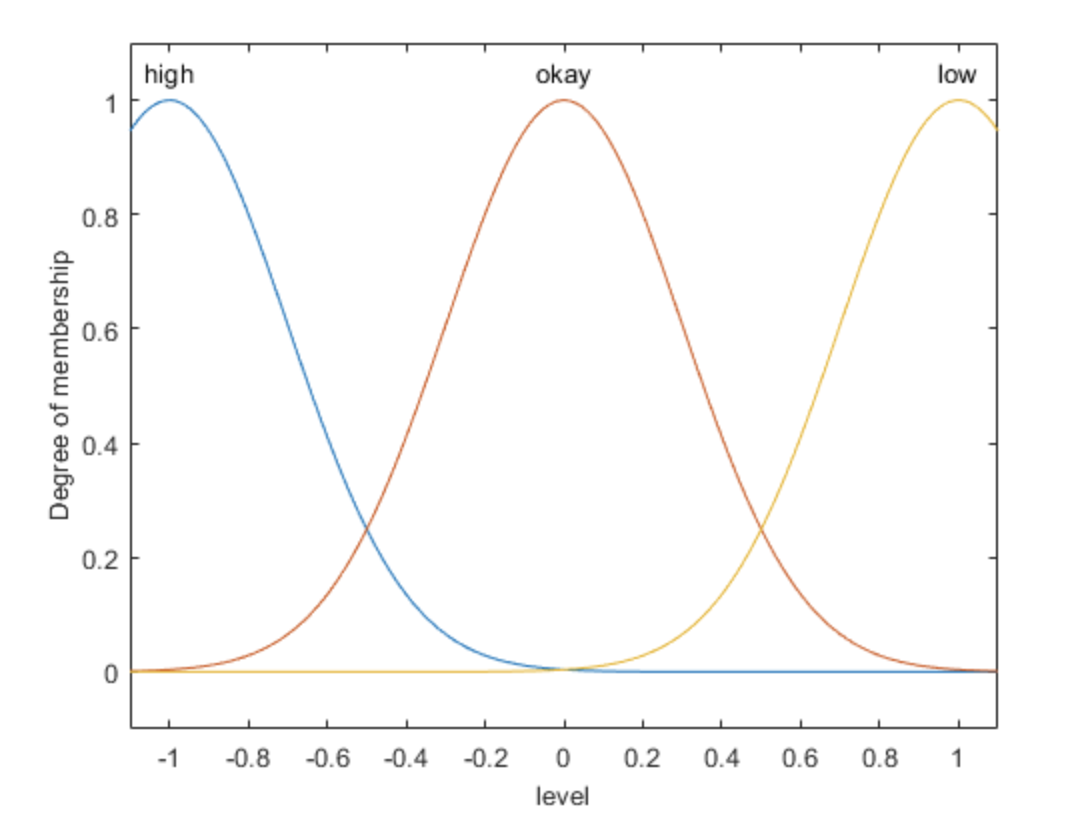

rate

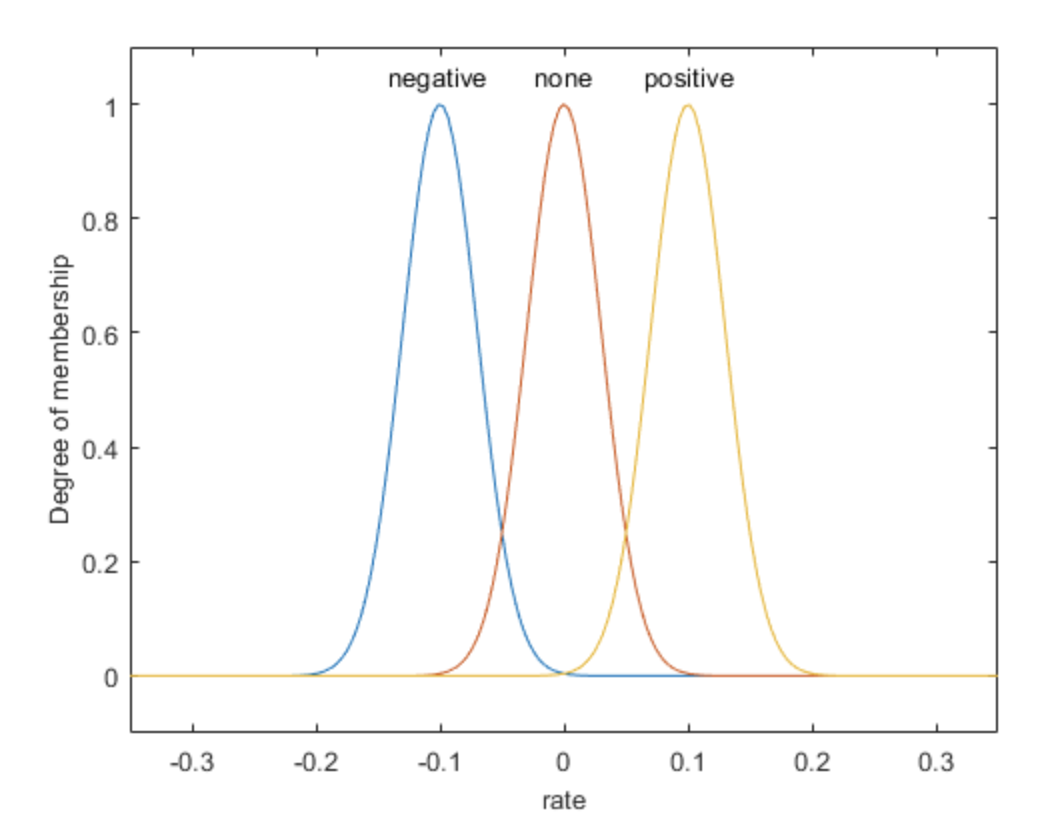

valve

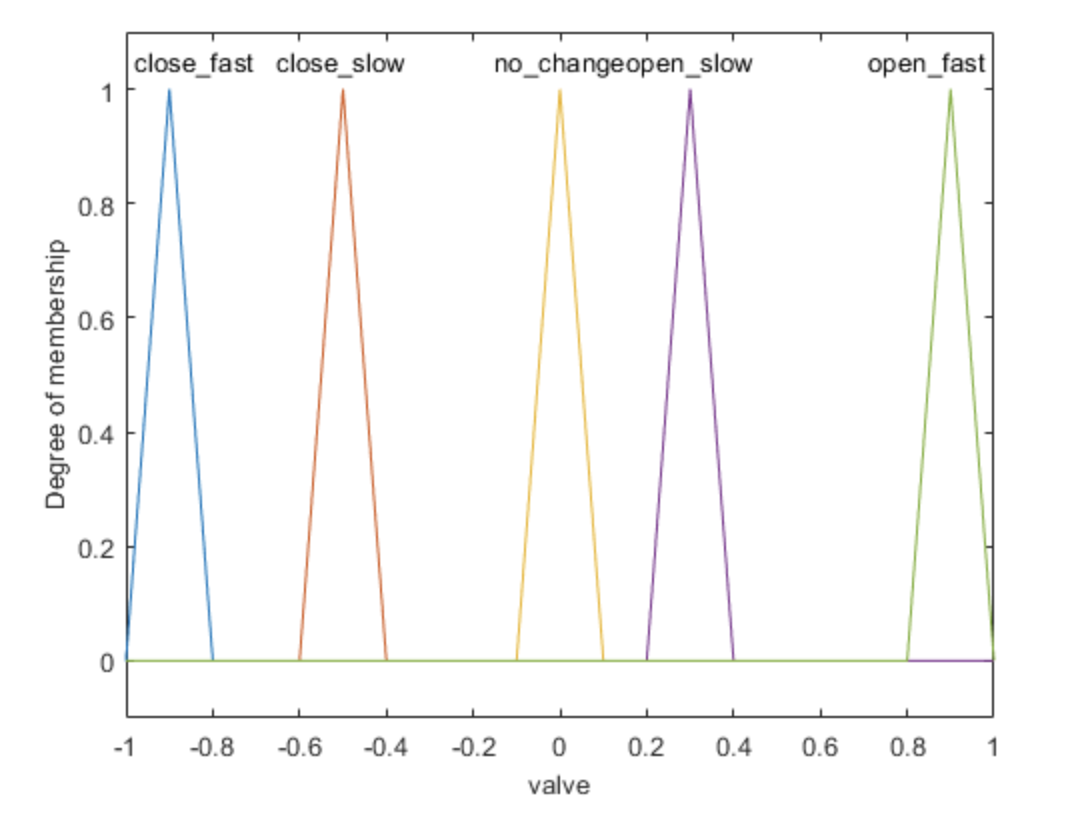

2.4 Muestra las reglas de inferencia difusa utilizadas

R.- Las reglas son;

   -  If the water level is okay, then do not adjust the valve.

   -  If the water level is low, then open the valve quickly.

   -  If the water level is high, then close the valve quickly.

   -  If the water level is okay and increasing, then close the valve slowly.

   -  If the water level is okay and decreasing, then open the valve slowly.

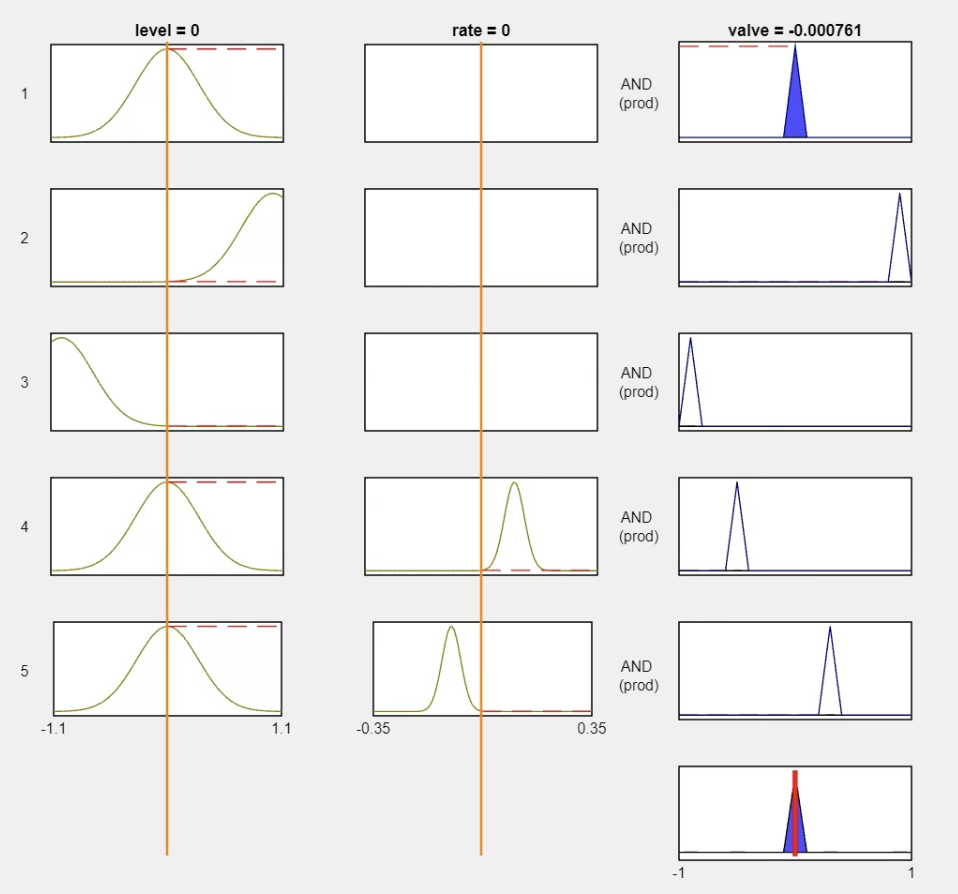

2.5 Explica en que consiste la implementación del sistema (una descripción general de todos bloques) en especial los bloque de visualización, así como la simulación mostrada.

R.- El sistema está pensado para el control del nivel del agua de un tanque por medio de una valvula, la salida depende del diametro de la pipa que es constante y de la presión que varia con el nivel del agua, por tanto es un sistema no lineal. El control difuso recibe dos entradas con tres funciones de membresia cada una, level que simboliza el nivel del agua para lo que se dan tres opciones; bajo, correcto y alto. Y rate que representa el cambio en el nivel del agua; ninguno, positivo y negativo. La salida indica que tan rapido o lento se va a cerrar o abrir la valvula de control, en este caso hay cinco funciones de membresia; cerrar rapido, cerrar lento, sin cambios, abrir lento y abrir rapido y este depende de las reglas que para este caso son las estableciadas en el punto anterior, las cuales nos indican que se prioriza el nivel del agua sobre el cambio y una vez que se garantiza el nivel da pie a fijarse en el cambio para mantener un nivel de agua uniforme.

## Problema 3

La lógica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

**Hela Lassoued, Raouf Ketata, ***Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification*, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506.

**3.1** ¿Qué factores explican la presencia de arritmias?

R.- Las arritmias se producen por un fallo en el sistema eléctrico del ritmo cardiaco, denominado sistema de excitación y conducción.

**3.2** ¿A qué se refieren las siglas DSS?

R.- Decision Support System ó Sistema de Soporte de Decisiones.

**3.3** ¿A qué se refieren las siglas FLC?

R.- Fussy Logic Controller ó Controlador de Logica Difusa.

**3.4** ¿A qué se refieren las siglas GA?

 R.- Genetic Algorithm ó Algoritmo Genetico.

**3.5** ¿Cuál es el principal objetivo del capítulo 5?

R.- Presentar un sistema de clasificación de arritmias basado en logica difusa.

**3.6**  La base de datos  *MIT-BIH Arrhythmia Database* contine varios registros de distintos tipos de arritmias, ¿Cuáles son estos?  

R.- Normal Sinus Rhythm (NSR), Premature Ventricular Contraction (PVC), Left Bundle Branch Block (LBBB), Right Bundle Branch Block (RBBB) and Paced beats (P).

**3.7** ¿De que depende el desempeño de un  FLC?

R.- Del uso del algoritmo genetico, de hecho, se muestran en el estudio los resultados del FLC antes de que se aplique este y despues, apreciandose un mejor rendimiento con el GA.

**3.8** ¿Para que utilizan un GA?

R.- Se usa para mejorar la eficacia del FLC.

**3.9** La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En que consisten las entradas (input features) que recibe este bloque de clasificación? 

R.- Consiste en un vector de características morfológicas obtenidas de la duración y amplitud de onda de cada registro de ECG.

**3.10** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?

R.- Para el mecanismo de inferencia de Mamdani, el antecedente y el consecuente son ambos variables difuzas, sin embargo para la inferencia de Sugeno, el antecedente es una variable difusa pero, el consecuente puede ser una constante o una función linear.

**3.11** De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüisticas se tienen? ¿Quñe tipo de conjuntos difusos son los conecuentes? ¿Cuantas reglas si-entones se proponen? ¿Que sistemas de inferencia se utiliza?   ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?

R.-**Variables linguisticas: 6**.

E1: the mean heart rate.

E2: the P wave amplitude.

E3: the PR interval duration.

E4: the QRS complex duration.

E5: the RR interval duration.

E6: the ST interval duration.

**Los conjuntos consecuentes son de tipo:** Singletons.

**La cantidad de reglas que se proponen son: **5.

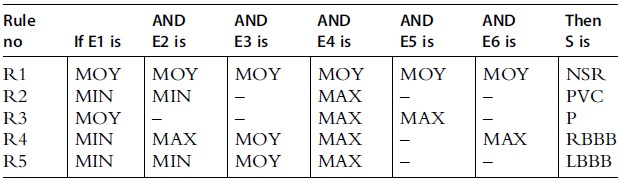

El sistema de inferencia difuso que se utiliza es el FIS tipo Mamdani.

Los operadores que se utilizan para la Conjunción, Disyunción e Implicación se muestra en la tabla siguiente:

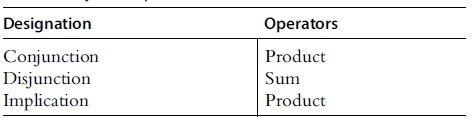

**3.12** Reporte el diagram de flujo del GA utilizado.

R.- 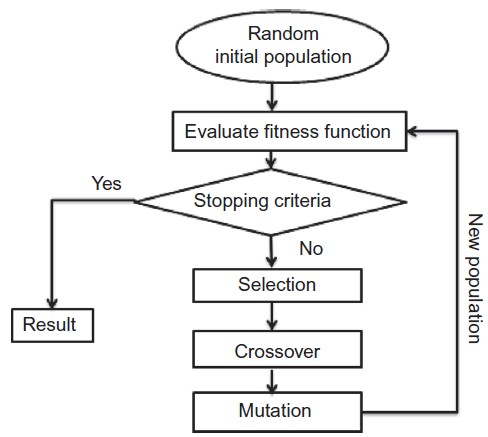

**3.13** Escriba la expresión matemática para la *fitness function*  utilizada.

R.- Root Mean Square Error o Media cruadrática del error.


$$\mathrm{RMSE}=\sqrt{\frac{1}{N}\sum_{i=0}^N {\left(t_i -o_i \right)}^2 }$$


Donde:

$o_i$ es la salida prevista.

$t_i$  es el objetivo correspondiente.

**3.14** No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parametros a optimizar se les da el nombre de *cromosomas. *En este caso ¿Qué representan los cromosomas? ¿Cuáles son los resultados del proceso de optimización?

R.- Los cromosomas representan los parámetros gaussianos ($\mu$ y $\delta$) y el npumero de reglas difusas.

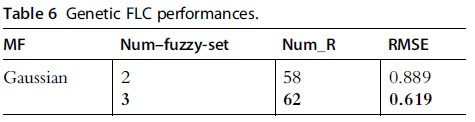

La imagen anterior indica que existe una tasa de cobertura entre los conjuntos difusos de entrada en comparación con su universo de discurso. Sin embargo, para la entrada E4, se muestra que los dos conjuntos difusos (MIN y MOY) se superponen. Entonces, para esta entrada, solo dos conjuntos difusos son suficientes para su fuzzificación.

**3.15** ¿Cuáles fueron los resultados de la implementación?

R.- Se encontró que el sistema FLC propuesto si bien no es perfecto y hay que seguir mejorando, es más interpretable y se define mejor que la aproximación de red neural.